rng(5)
pwlregions_init
gcp;
net = RandomPWANetwork(2,[10,5,2])

net =   RandomPWANetwork with properties:

     layers: [1×3 struct]
    regions: []
       root: []


regs = net.pwa('input_space', makebox(2,5), 'max_depth', i);
lens = arrayfun(@(x) size(x.H,1), regs);
max_depth = max(lens)

max_depth = 16

for i = 1:max_depth+1
    net.pwa('input_space', makebox(2,5), 'max_depth', i)
    figure;
    net.plot_output(1)
end

Array of 2 polyhedra.


Array of 4 polyhedra.


Array of 8 polyhedra.


Array of 16 polyhedra.


Array of 29 polyhedra.


rng(0239)


bignet = RandomPWANetwork(2, [10,20,10,1])

bignet =   RandomPWANetwork with properties:

     layers: [1×4 struct]
    regions: []
       root: []


root = makebox(2,5);
% regs = bignet.pwa('input_space', root, 'max_depth', 10,'lsqr_approx', false)
regs = bignet.pwa('input_space', root, 'min_diameter', 0.5,'lsqr_approx', false)

Array of 319 polyhedra.


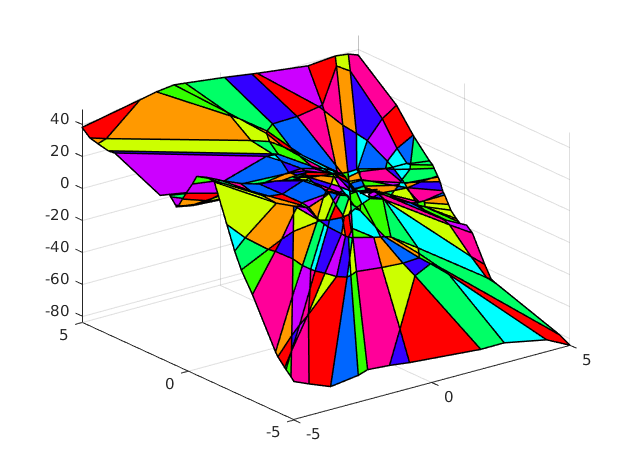

bignet.plot_output(1)
saveas(gcf,'truncated.eps', 'epsc')

disp("Limited: "+length(regs))

Limited: 319


root2 = makebox(2,5);
% regs2 = bignet.pwa('input_space', root2, 'max_depth', 10, 'lsqr_approx', true)
regs2 = bignet.pwa('input_space', root, 'min_diameter', 0.5,'lsqr_approx', true)

Array of 320 polyhedra.


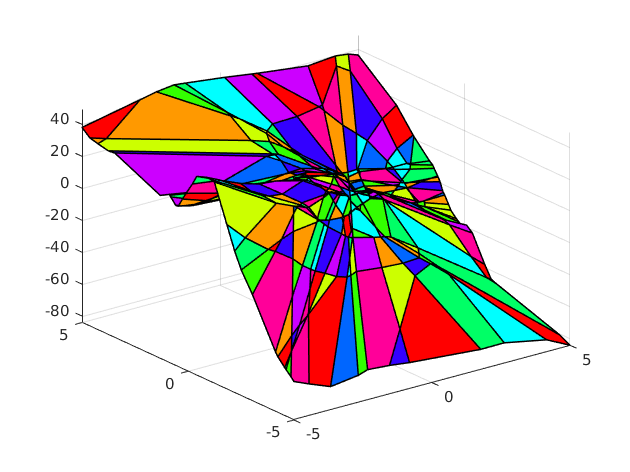

bignet.plot_output(1)
saveas(gcf,'truncated_lsqr.eps', 'epsc')

disp("Lsqr: "+length(regs2))

Lsqr: 320


root3 = makebox(2,5);
regs_exact = bignet.pwa('input_space', root3)

Array of 461 polyhedra.


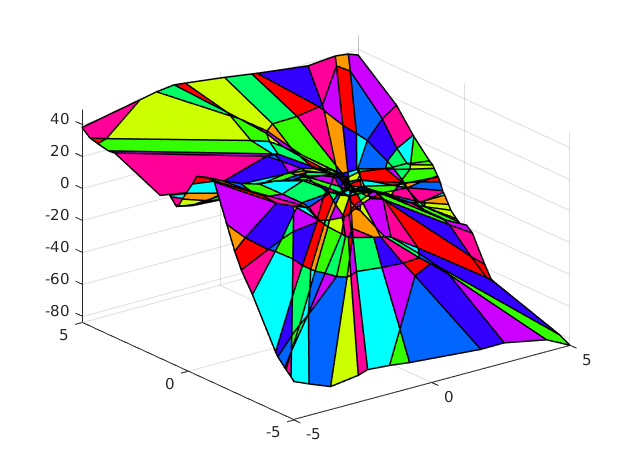

bignet.plot_output(1)
saveas(gcf,'exact.eps', 'epsc')

disp("Exact: "+length(regs_exact))

Exact: 461


regs

Array of 228 polyhedra.


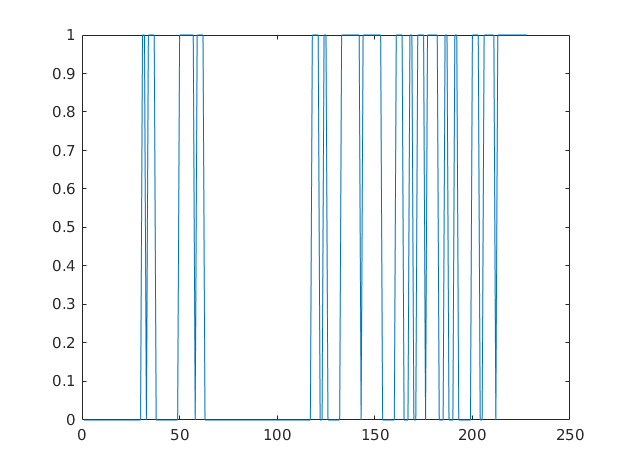


truncated = arrayfun(@(x) isfield(x.Data, 'truncate'), regs);
plot( truncated)


depths = arrayfun(@(x) x.Data.depth, regs);
min(depths), mean(depths), max(depths)

ans = 4

ans = 8.8114

ans = 10